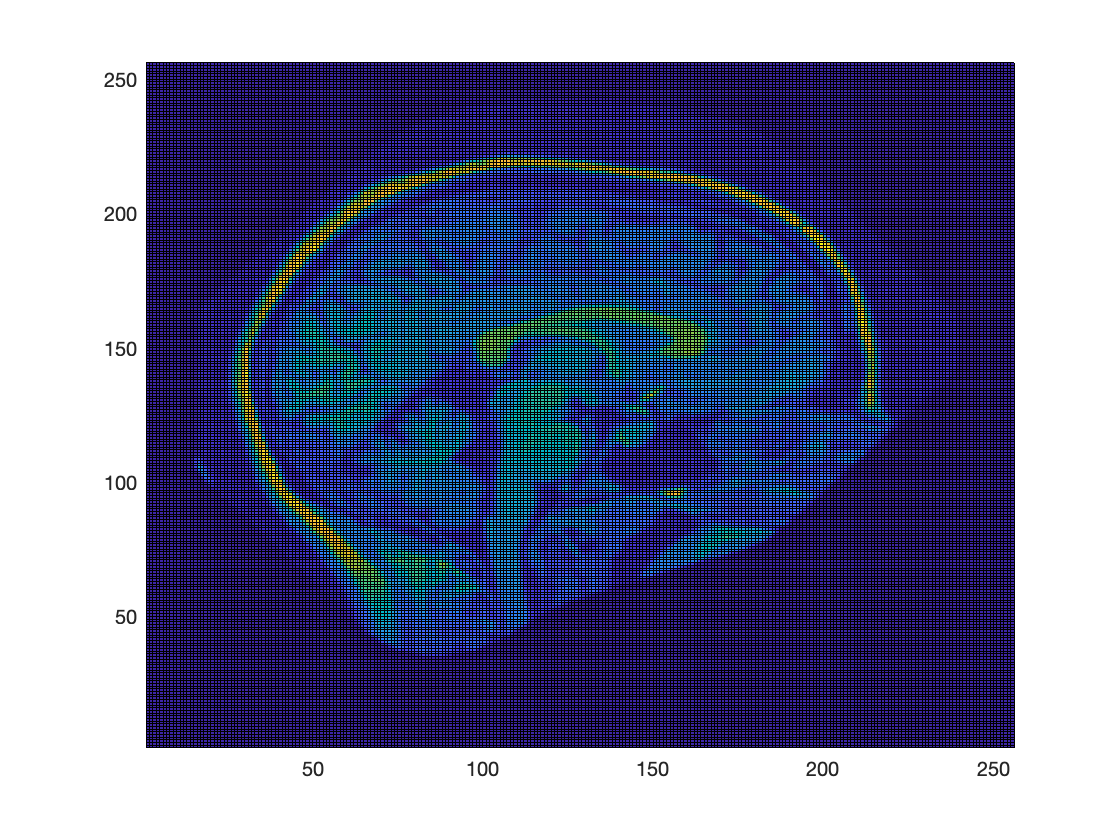

load 'greyimages.mat' ;
colorbar;

TEST_CASE = 32;
I = reshape(greyimages(:,TEST_CASE),256, 256);
I = rescale(I,0,255);
I = imgaussfilt(I,0.5);
% [Gx,Gy] = imgradientxy(I);
dim = size(I,1);
pcolor(I)

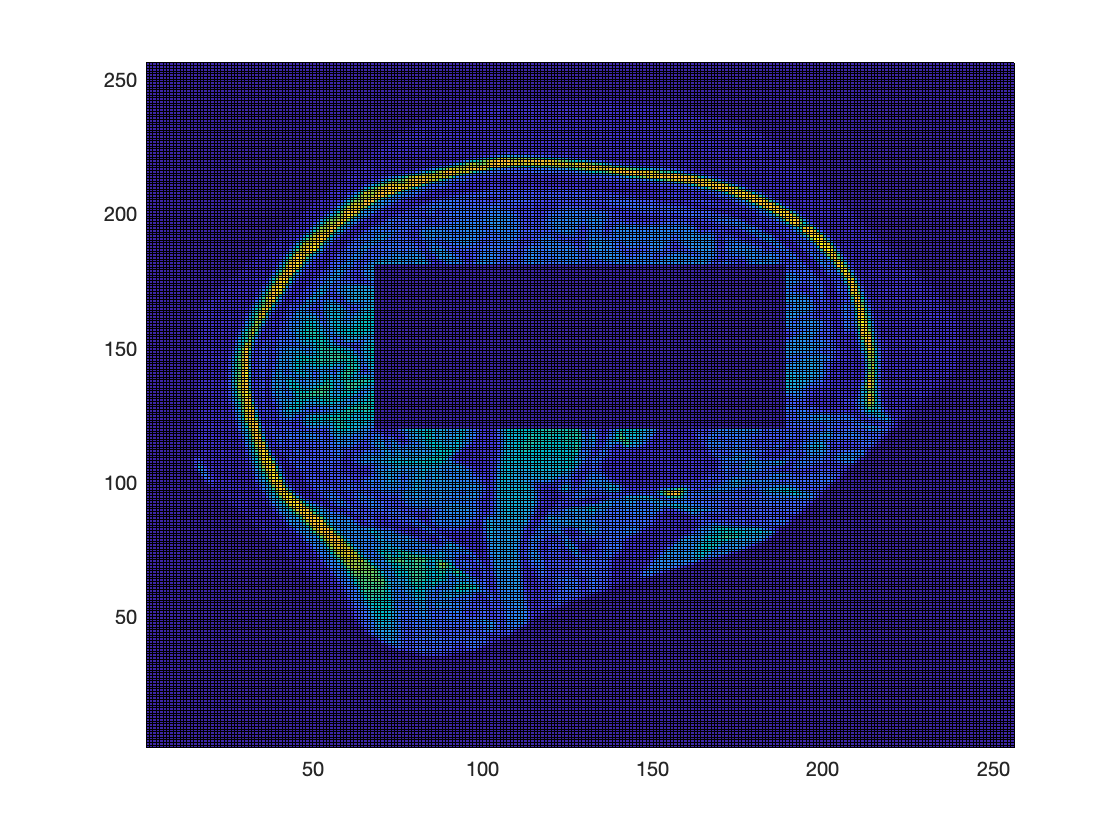

I1 =I;
sz=30;
y_region = 150-sz:150+sz; x_region =128-2*sz:128+2*sz;
I1(y_region,x_region)=0;
pcolor(I1)

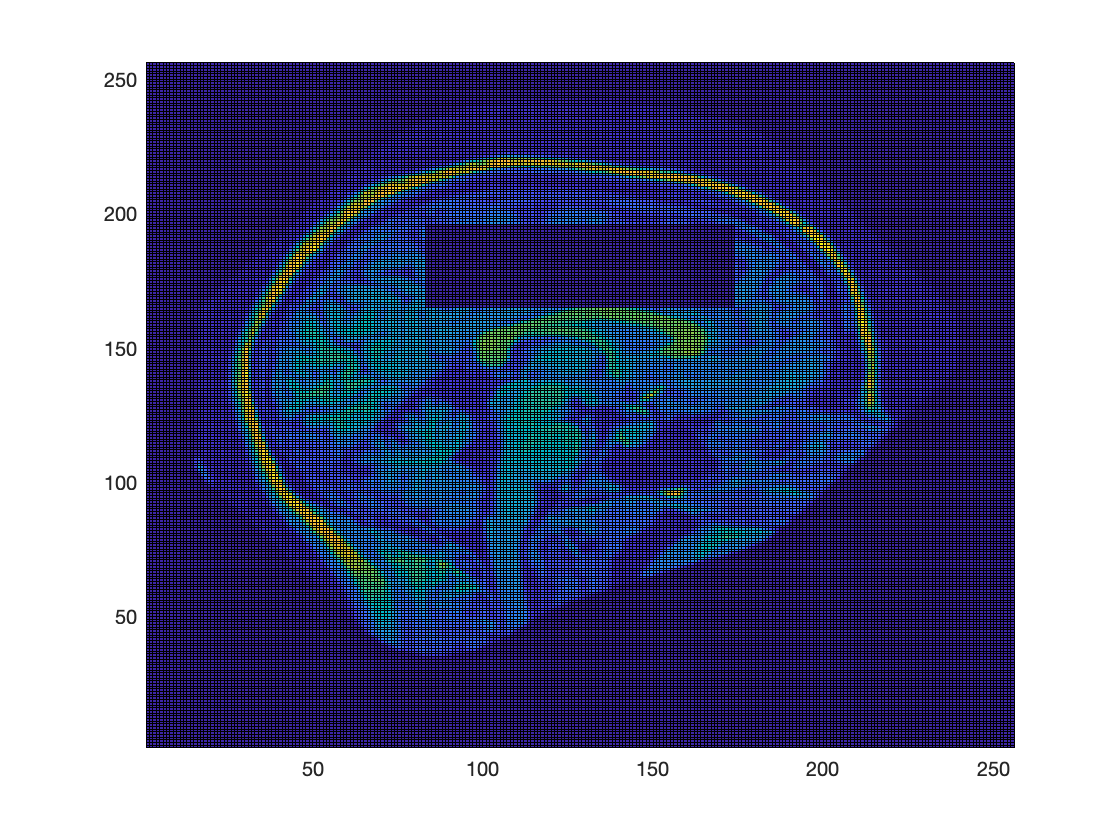


I1=I;
y_region = 180-sz/2:180+sz/2; x_region =128-1.5*sz:128+1.5*sz;
I1(y_region,x_region)=0;
pcolor(I1)



box=I(y_region,x_region);
wm = mean(box(:))

wm = 61.3462

sd = std(box(:))

sd = 13.9258

Get pixels that are within 1 SD from WM_mean

wm=61;sd=13;

sdw = 1*sd

sdw = 13

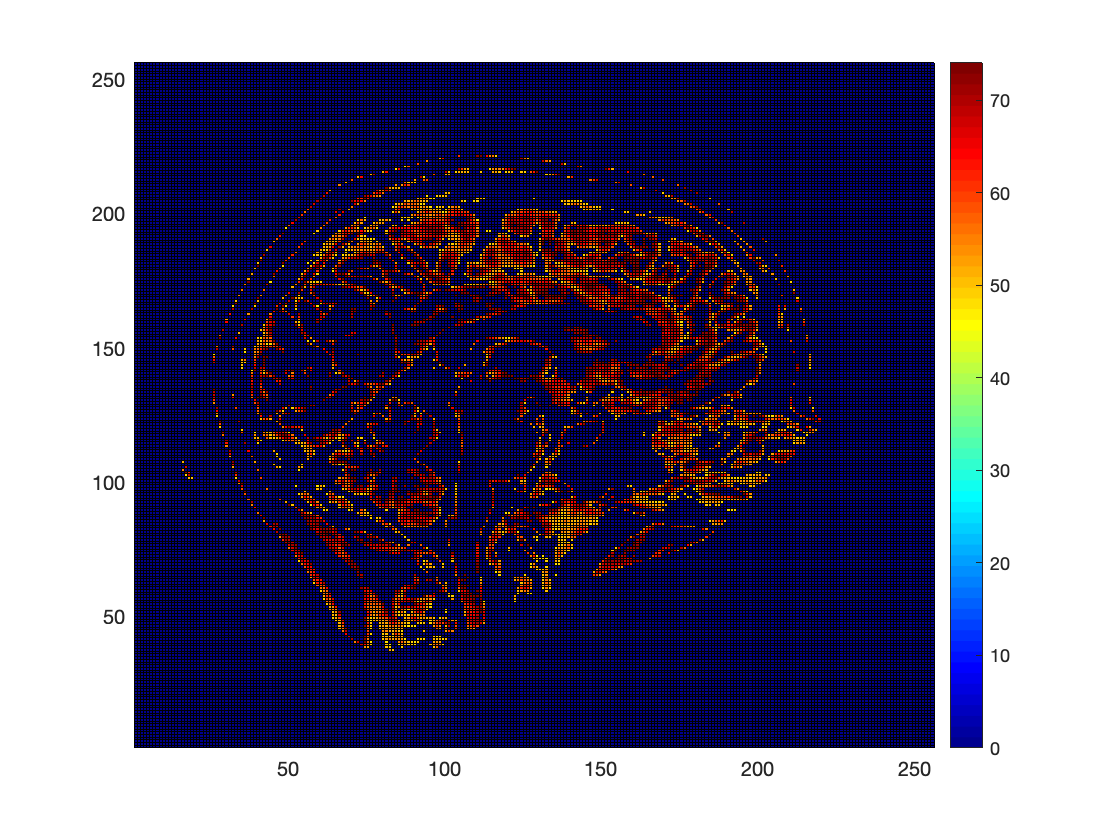

wm_low = wm-sdw; wm_high = wm+sdw;
I1=I;
I1(I<wm_low | I>wm_high)= 0;
pcolor(I1); colorbar; colormap('jet')

% sorted=sort(I(:));
% numpixels = size(sorted);
% quartile = int(0.9*numpixels) % 90th percentile
% sorted()

skull=151;

box = I(I > skull);
sm = mean(box(:))

sm = 179.7932

sd = std(box(:))

sd = 20.8026

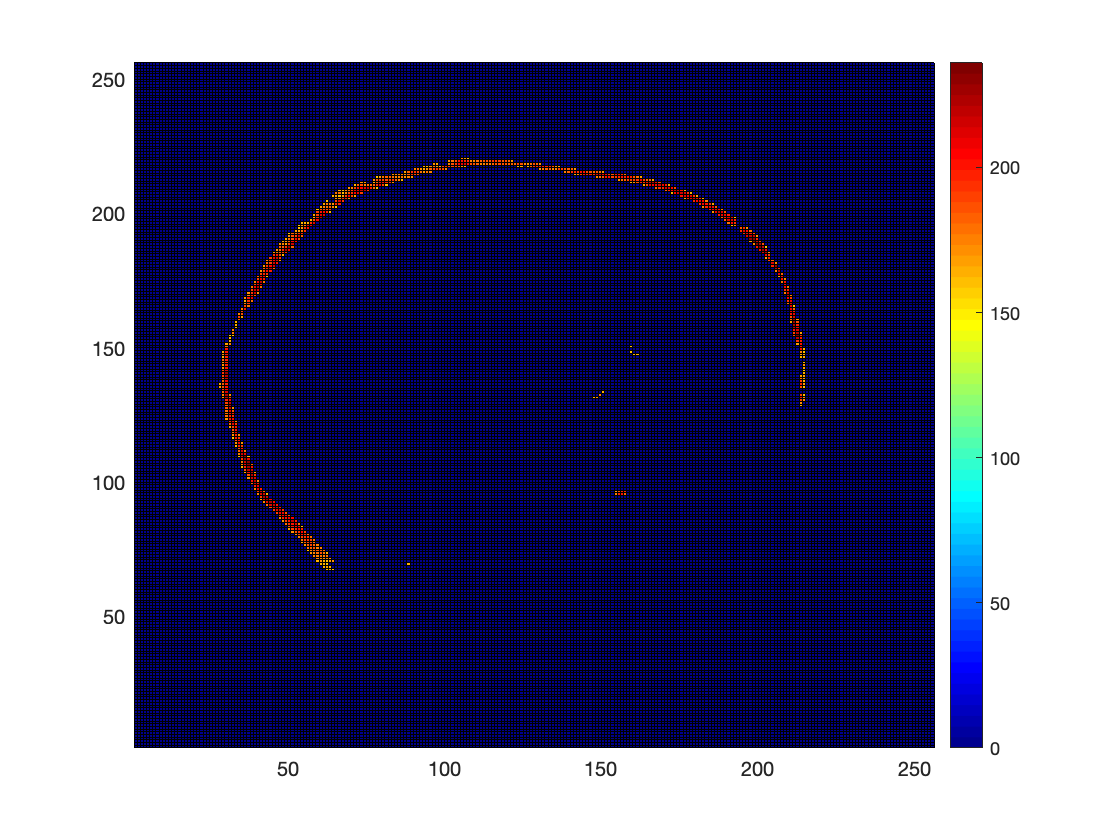


sm_low = sm-1.5*sdw; sm_high = sm+sdw;
I1=I;
I1(I<sm_low)= 0;
pcolor(I1); colorbar; colormap('jet')